# Original

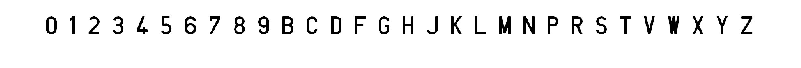

I = rgb2gray(imread('Joc_de_caracters.jpg'));
imshow(I)

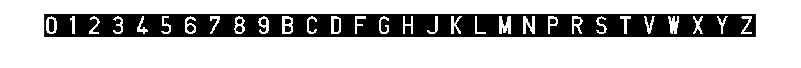

BW = I<126;
imshow(BW)

CC = bwconncomp(BW);
props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]'; 
Y =  ['0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; '9'; 'B'; 'C'; 'D'; 'F'; 'G'; 'H'; 'J'; 'K'; 'L'; 'M'; 'N'; 'P'; 'R'; 'S'; 'T'; 'V'; 'W'; 'X'; 'Y'; 'Z'];
Classifier = TreeBagger(100,X,Y);
[Ypredicted, certainty] = predict(Classifier,X);
table(Classifier.ClassNames,Ypredicted,max(certainty,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}    0.69 
    {'1'}    {'1'}    0.62 
    {'2'}    {'2'}    0.68 
    {'3'}    {'3'}    0.73 
    {'4'}    {'4'}    0.67 
    {'5'}    {'5'}    0.58 
    {'6'}    {'6'}    0.64 
    {'7'}    {'7'}    0.54 
    {'8'}    {'8'}     0.6 
    {'9'}    {'9'}    0.65 
    {'B'}    {'B'}    0.63 
    {'C'}    {'C'}    0.71 
    {'D'}    {'D'}    0.65 
    {'F'}    {'F'}    0.62 
    {'G'}    {'G'}    0.51 
    {'H'}    {'H'}    0.66 


PL = cell2mat(Ypredicted);
TL = cell2mat(num2cell(Y));
encerts = sum(PL == TL)

encerts = 30

percentatge_encerts = encerts/ size(Y,1) 

percentatge_encerts = 1

%%com era d'esperar, el percentatge d'encerts es del 100% buscant sobre
%%l'imatge original

# Resize

Ig = imresize(I,15);
BW = Ig<126;
CC = bwconncomp(BW);
props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]';
[label,score] = predict(Classifier,X);
% mostrem el resultat mes probable i la seva puntuació (score)
table(Classifier.ClassNames,label,max(score,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'Z'}    0.29 
    {'1'}    {'Z'}    0.29 
    {'2'}    {'Z'}    0.29 
    {'3'}    {'Z'}    0.29 
    {'4'}    {'Z'}    0.29 
    {'5'}    {'Z'}    0.29 
    {'6'}    {'Z'}    0.29 
    {'7'}    {'Z'}    0.29 
    {'8'}    {'Z'}    0.29 
    {'9'}    {'Z'}    0.29 
    {'B'}    {'Z'}    0.29 
    {'C'}    {'Z'}    0.29 
    {'D'}    {'Z'}    0.29 
    {'F'}    {'Z'}    0.29 
    {'G'}    {'Z'}    0.29 
    {'H'}    {'Z'}    0.29 


PL = cell2mat(label);
TL = cell2mat(num2cell(Y));
encerts = sum(PL == TL)

encerts = 1

percentatge_encerts = encerts / size(Y,1)

percentatge_encerts = 0.0333

%% com podem veure el Classifier original no funciona molt bé quan fem un resize de la imatge, 
% per tant intentem crear-ne un que funcioni independentment de la mida de
% l'imatge
props = regionprops('table',BW,'Area','Perimeter','BoundingBox');
C1 = props.Area./(props.Perimeter.*props.Perimeter);
C2 = props.Perimeter./(props.BoundingBox(:,3)); %W
C3 = props.Perimeter./(props.BoundingBox(:,4)); %H
C4 = props.BoundingBox(:,3)./props.BoundingBox(:,4); %W/H
X = [C1 C2 C3 C4];
BetterClassifier = TreeBagger(100,X,Y);
[Ypredicted, certainty] = predict(BetterClassifier,X);
table(BetterClassifier.ClassNames,Ypredicted,max(certainty,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}     0.6 
    {'1'}    {'1'}    0.52 
    {'2'}    {'2'}    0.57 
    {'3'}    {'3'}    0.65 
    {'4'}    {'4'}     0.6 
    {'5'}    {'5'}    0.64 
    {'6'}    {'6'}    0.62 
    {'7'}    {'7'}    0.65 
    {'8'}    {'8'}    0.69 
    {'9'}    {'9'}    0.75 
    {'B'}    {'B'}    0.64 
    {'C'}    {'C'}    0.63 
    {'D'}    {'D'}    0.65 
    {'F'}    {'F'}    0.62 
    {'G'}    {'G'}    0.72 
    {'H'}    {'H'}    0.61 


PL = cell2mat(Ypredicted);
TL = cell2mat(num2cell(Y));
encerts = sum(PL == TL)

encerts = 30

percentatge_encerts = encerts/ size(Y,1)

percentatge_encerts = 1

%%fent que es tingui en compte la proporció en comptes de la mangitud,
%%creem un classifier que funciona per a totes les mides de imatge

# Caràcters deformats

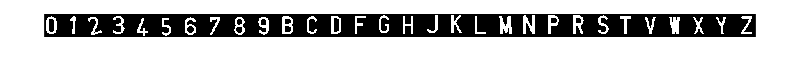

I = rgb2gray(imread('Joc_de_caracters_deformats.jpg'));
BI = I < 128; % separem el background
imshow(BI);

CC = bwconncomp(BI);
props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]'; 
[label,score] = predict(Classifier,X);

% mostrem el resultat mes probable i la seva puntuació (score)
table(Classifier.ClassNames,label,max(score,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}    0.69 
    {'1'}    {'1'}    0.45 
    {'2'}    {'2'}    0.54 
    {'3'}    {'K'}    0.14 
    {'4'}    {'4'}    0.65 
    {'5'}    {'5'}     0.5 
    {'6'}    {'6'}    0.54 
    {'7'}    {'7'}    0.54 
    {'8'}    {'8'}     0.6 
    {'9'}    {'9'}    0.55 
    {'B'}    {'B'}    0.59 
    {'C'}    {'C'}    0.53 
    {'D'}    {'D'}    0.65 
    {'F'}    {'F'}    0.62 
    {'G'}    {'G'}    0.45 
    {'H'}    {'H'}    0.66 


PL = cell2mat(label);
TL = cell2mat(num2cell(Y));
encerts = sum(PL == TL)

encerts = 24

percentatge_encerts = encerts / size(Y,1)

percentatge_encerts = 0.8000

%% amb el classifier original ens dona resultats força bons, anem a probar amb el proprcional

props = regionprops('table',BW,'Area','Perimeter','BoundingBox');
C1 = props.Area./(props.Perimeter.*props.Perimeter);
C2 = props.Perimeter./(props.BoundingBox(:,3)); %W
C3 = props.Perimeter./(props.BoundingBox(:,4)); %H
C4 = props.BoundingBox(:,3)./props.BoundingBox(:,4); %W/H
X = [C1 C2 C3 C4];
[Ypredicted, certainty] = predict(BetterClassifier,X);
table(BetterClassifier.ClassNames,Ypredicted,max(certainty,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}     0.6 
    {'1'}    {'1'}    0.52 
    {'2'}    {'2'}    0.57 
    {'3'}    {'3'}    0.65 
    {'4'}    {'4'}     0.6 
    {'5'}    {'5'}    0.64 
    {'6'}    {'6'}    0.62 
    {'7'}    {'7'}    0.65 
    {'8'}    {'8'}    0.69 
    {'9'}    {'9'}    0.75 
    {'B'}    {'B'}    0.64 
    {'C'}    {'C'}    0.63 
    {'D'}    {'D'}    0.65 
    {'F'}    {'F'}    0.62 
    {'G'}    {'G'}    0.72 
    {'H'}    {'H'}    0.61 


PL = cell2mat(Ypredicted);
TL = cell2mat(num2cell(Y));
encerts = sum(PL == TL)

encerts = 30

percentatge_encerts = encerts/ size(Y,1)

percentatge_encerts = 1

%%sembla que també funciona millor que l'original, pero creiem q es deu a
%%que la deformació no es gaire pronunciada

# Descriptors de forma

%% Probem a fer servir els descriptors que creiem que no tenen en compte l'area, si no la forma
%% en el nostre cas: circularity, eccentricty, eulerNumber, extent.

%%probem primer sobre l'imatge original
I = rgb2gray(imread('Joc_de_caracters.jpg'));
BW = I<126;
CC = bwconncomp(BW);
props = regionprops(CC,'Circularity','Extent','Eccentricity','EulerNumber');
X = [props.Circularity; props.Extent; props.Eccentricity; props.EulerNumber]';
Y =  ['0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; '9'; 'B'; 'C'; 'D'; 'F'; 'G'; 'H'; 'J'; 'K'; 'L'; 'M'; 'N'; 'P'; 'R'; 'S'; 'T'; 'V'; 'W'; 'X'; 'Y'; 'Z'];
FormClassifier = TreeBagger(100,X,Y);
[Ypredicted, certainty] = predict(FormClassifier,X);
table(BetterClassifier.ClassNames,Ypredicted,max(certainty,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}    0.58 
    {'1'}    {'1'}    0.65 
    {'2'}    {'2'}    0.66 
    {'3'}    {'3'}    0.72 
    {'4'}    {'4'}    0.67 
    {'5'}    {'5'}    0.66 
    {'6'}    {'6'}    0.64 
    {'7'}    {'7'}     0.7 
    {'8'}    {'8'}    0.53 
    {'9'}    {'9'}    0.62 
    {'B'}    {'B'}    0.68 
    {'C'}    {'C'}    0.63 
    {'D'}    {'D'}    0.69 
    {'F'}    {'F'}    0.62 
    {'G'}    {'G'}    0.64 
    {'H'}    {'H'}    0.69 


PL = cell2mat(Ypredicted);
TL = cell2mat(num2cell(Y));
encerts = sum(PL == TL)

encerts = 30

percentatge_encerts = encerts/ size(Y,1) 

percentatge_encerts = 1

%%sembla que dona bons resultats sobre l'original, anem a probar amb els
%%caràcters deformats

I = rgb2gray(imread('Joc_de_caracters_deformats.jpg'));
BW = I<126;
CC = bwconncomp(BW);
props = regionprops(CC,'Circularity','Extent','Eccentricity','EulerNumber');
X = [props.Circularity; props.Extent; props.Eccentricity; props.EulerNumber]';
Y =  ['0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; '9'; 'B'; 'C'; 'D'; 'F'; 'G'; 'H'; 'J'; 'K'; 'L'; 'M'; 'N'; 'P'; 'R'; 'S'; 'T'; 'V'; 'W'; 'X'; 'Y'; 'Z'];
[Ypredicted, certainty] = predict(FormClassifier,X);
table(FormClassifier.ClassNames,Ypredicted,max(certainty,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}    0.58 
    {'1'}    {'1'}    0.52 
    {'2'}    {'Y'}    0.27 
    {'3'}    {'V'}    0.29 
    {'4'}    {'4'}    0.66 
    {'5'}    {'5'}    0.52 
    {'6'}    {'6'}    0.54 
    {'7'}    {'7'}     0.7 
    {'8'}    {'8'}    0.53 
    {'9'}    {'9'}     0.5 
    {'B'}    {'B'}    0.45 
    {'C'}    {'C'}    0.53 
    {'D'}    {'D'}    0.69 
    {'F'}    {'F'}    0.62 
    {'G'}    {'G'}    0.61 
    {'H'}    {'H'}    0.69 


PL = cell2mat(Ypredicted);
TL = cell2mat(num2cell(Y));
encerts = sum(PL == TL)

encerts = 26

percentatge_encerts = encerts/ size(Y,1) 

percentatge_encerts = 0.8667

%% fent servir els descriptors de forma ens dona millors resulatats que amb el proporcional,
%% creiem que el FormClassifier donara resultats molt millors que l'altre en imatges amb deformacions més dràstiques

# Experimentació amb matricules

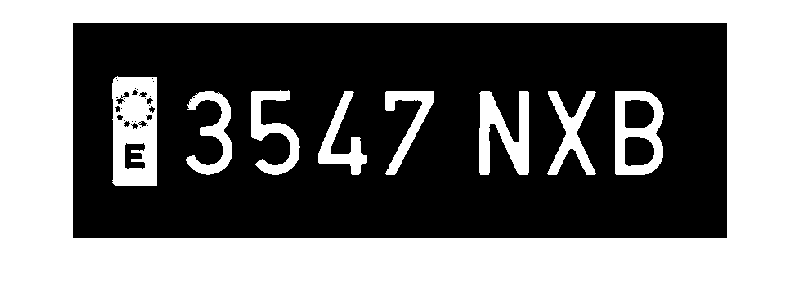

I = rgb2gray(imread('matricula1.jpg'));
BW = I<40;
imshow(BW);

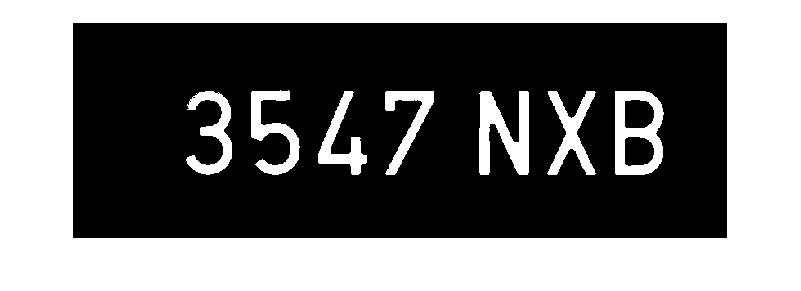

CC = bwconncomp(BW);
%% borrem el primer element que trobem(escaneja columna per columna, de esquerra a dreta)
%% es a dir, la part blava de la matricula
BW(CC.PixelIdxList{1})=0;
imshow(BW)

CC = bwconncomp(BW);
props = regionprops('table',BW,'Area','Perimeter','BoundingBox');
C1 = props.Area./(props.Perimeter.*props.Perimeter);
C2 = props.Perimeter./(props.BoundingBox(:,3)); %W
C3 = props.Perimeter./(props.BoundingBox(:,4)); %H
C4 = props.BoundingBox(:,3)./props.BoundingBox(:,4); %W/H
X = [C1 C2 C3 C4];
Yexpected = {'3';'5';'4';'7';'N';'X';'B';}

Yexpected = 7×1 cell array
    {'3'}
    {'5'}
    {'4'}
    {'7'}
    {'N'}
    {'X'}
    {'B'}


[Ypredicted, certainty] = predict(BetterClassifier,X);
Ypredicted

Ypredicted = 7×1 cell array
    {'5'}
    {'G'}
    {'4'}
    {'4'}
    {'N'}
    {'3'}
    {'P'}


percentatge_encerts = sum(strcmp(Ypredicted,Yexpected))/7

percentatge_encerts = 0.2857

%% podem veure que no funciona gaire bé (nomes encerta 2/7) , anem a probar amb l'altre Classifier

props = regionprops(CC,'Circularity','Extent','Eccentricity','EulerNumber');
X = [props.Circularity; props.Extent; props.Eccentricity; props.EulerNumber]';
Yexpected = {'3';'5';'4';'7';'N';'X';'B';}

Yexpected = 7×1 cell array
    {'3'}
    {'5'}
    {'4'}
    {'7'}
    {'N'}
    {'X'}
    {'B'}


[Ypredicted, certainty] = predict(FormClassifier,X);
Ypredicted

Ypredicted = 7×1 cell array
    {'5'}
    {'G'}
    {'Y'}
    {'Y'}
    {'N'}
    {'S'}
    {'D'}


percentatge_encerts = sum(strcmp(Ypredicted,Yexpected))/7

percentatge_encerts = 0.1429

%%sembla que el formClassifier dona encara pitjors resultats que l'anterior

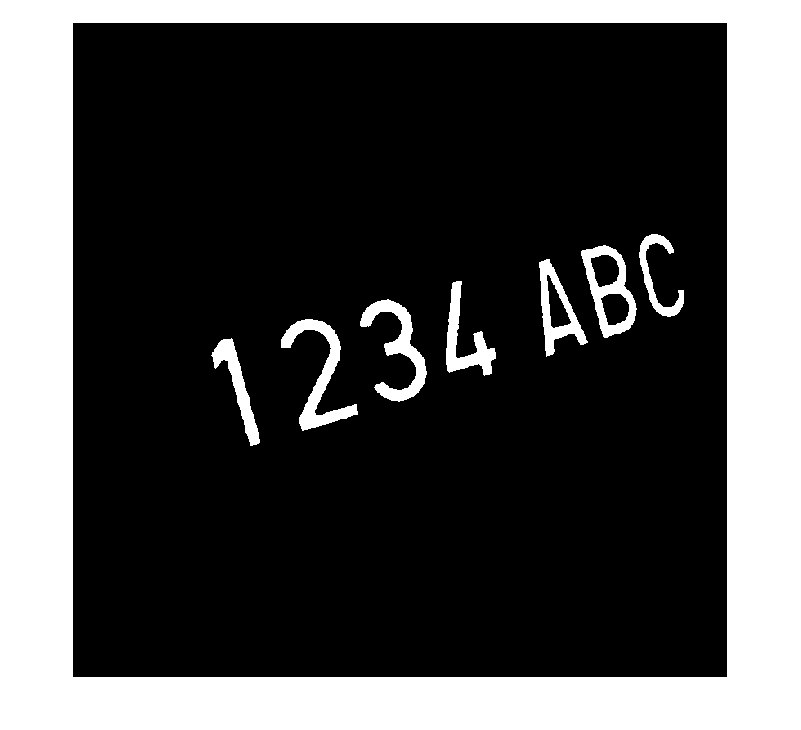

%porbem amb una segona matriucla

I = rgb2gray(imread('matricula2.jpg'));
BW = I<40;
imshow(BW);

CC = bwconncomp(BW);
props = regionprops('table',BW,'Area','Perimeter','BoundingBox');
C1 = props.Area./(props.Perimeter.*props.Perimeter);
C2 = props.Perimeter./(props.BoundingBox(:,3)); %W
C3 = props.Perimeter./(props.BoundingBox(:,4)); %H
C4 = props.BoundingBox(:,3)./props.BoundingBox(:,4); %W/H
X = [C1 C2 C3 C4];
Yexpected = {'1';'2';'3';'4';'A';'B';'C';}

Yexpected = 7×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'A'}
    {'B'}
    {'C'}


[Ypredicted, certainty] = predict(BetterClassifier,X);
Ypredicted

Ypredicted = 7×1 cell array
    {'1'}
    {'6'}
    {'6'}
    {'C'}
    {'P'}
    {'0'}
    {'G'}


percentatge_encerts = sum(strcmp(Ypredicted,Yexpected))/7

percentatge_encerts = 0.1429

%% funciona pitjor que en el cas anterior, ja que la matricula no esta recta, anem a probar amb el de forma,
%% el qual abans a donat millors resultats amb les deformacions

props = regionprops(CC,'Circularity','Extent','Eccentricity','EulerNumber');
X = [props.Circularity; props.Extent; props.Eccentricity; props.EulerNumber]';
Yexpected = {'1';'2';'3';'4';'A';'B';'C';}

Yexpected = 7×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'A'}
    {'B'}
    {'C'}


[Ypredicted, certainty] = predict(FormClassifier,X);
Ypredicted

Ypredicted = 7×1 cell array
    {'J'}
    {'Y'}
    {'Y'}
    {'7'}
    {'Y'}
    {'7'}
    {'J'}


percentatge_encerts = sum(strcmp(Ypredicted,Yexpected))/7

percentatge_encerts = 0

%% el de forma no consegueix encertar cap de dels caràcters